# Arduino-Controlled LM317 DC Power Supply

1 Nov 22 B. Rasnow

## Objective

Construct a quantitatively accurate model of the Arduino controlled voltage regulator circuit we've build. At first, I didn't think this was worthwhile, but it isn't terribly hard -- and really will test our understanding of the theory, and practice some Matlab programming. So let's give it a try. What pwm value should we simulate? How about all of them ;-)! 

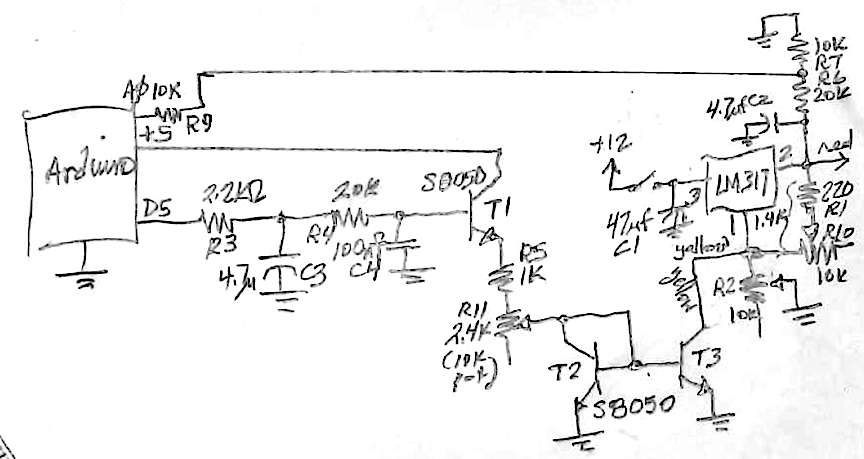

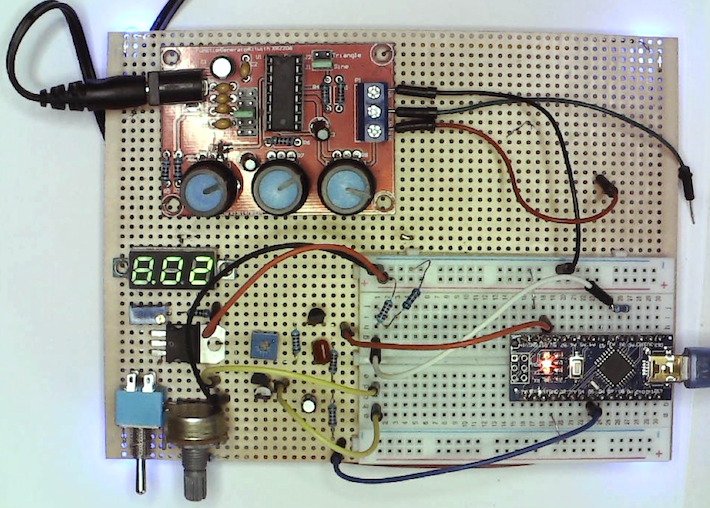

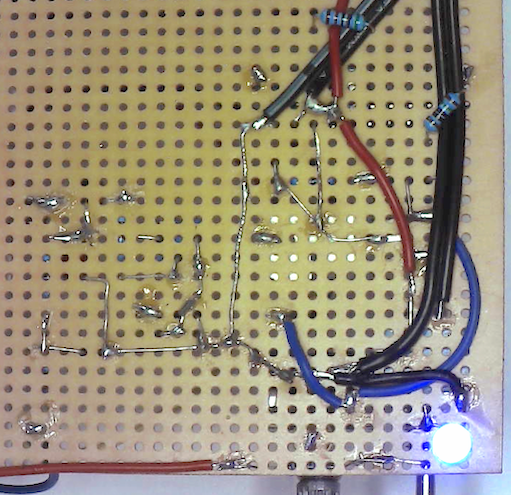

    Figure 1. Schematic, top view, and bottom view of the circuit. The 2 resistors on the bottom function just as insulated strain relief clamps for the power cords. There are also 5 LEDs on the bottom corners and middle of the board which serve as feet, keeping the wiring elevated on the table. They are wired in series as power indicators. 

## Measuring circuit performance

 Let's set a range of pwm values and measure the resulting voltages. We could instead set a range of voltages using volts2pwm, but that involves an empirical polynomial that I'd rather not mix into the model (yet). Keep it simple

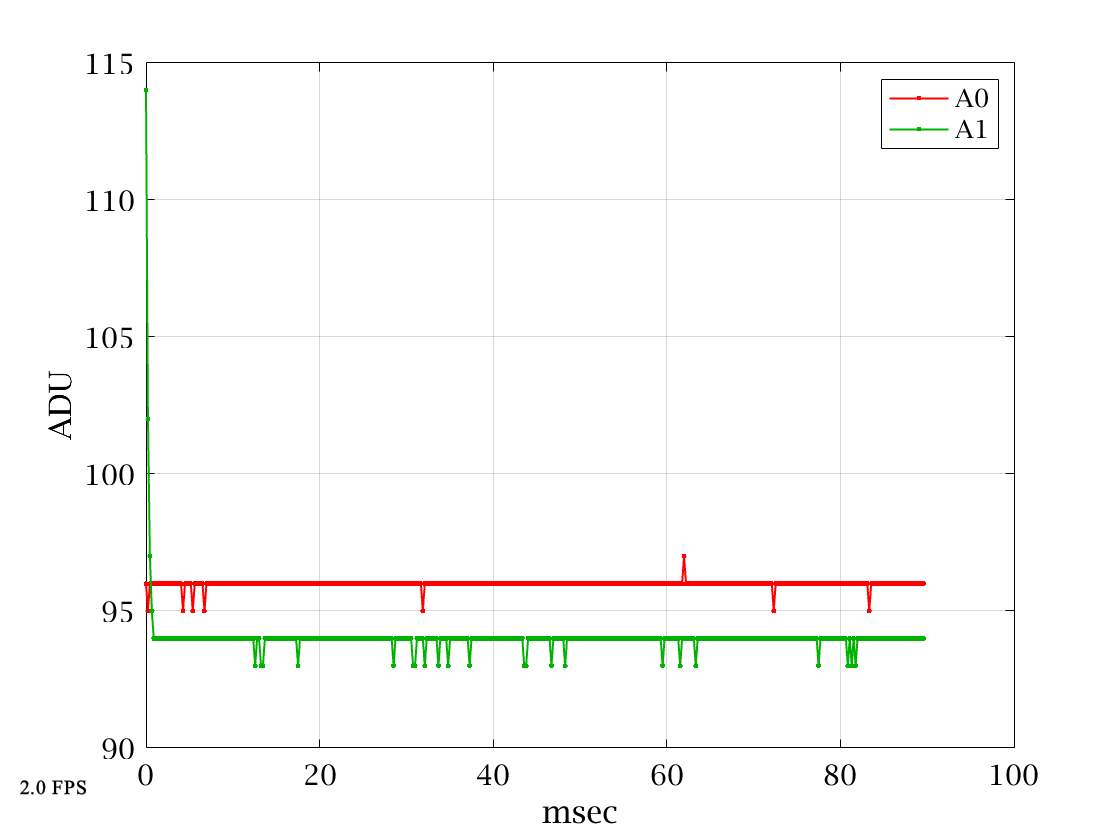

vref = 4.62; % volts on vref pin
R7 = 9.92e3; 
R6 = 20.08e3; 
pwm = (50:5:255)'; % 42 different values
v317 = zeros(size(pwm));
oscope1; % initialize ard
tic; 
for i=1:length(pwm)
    writeline(ard,['p' num2str(pwm(i))]);
    pause(.2); % extra time for the voltage to stabilize
    runOnce = true;
    oscope1; % --> new data = [A0 A1]
    v317(i) = vref * mean(data(:,1)) / 1023 * (R6+R7)/R7; 
end

toc  

Elapsed time is 24.168855 seconds.


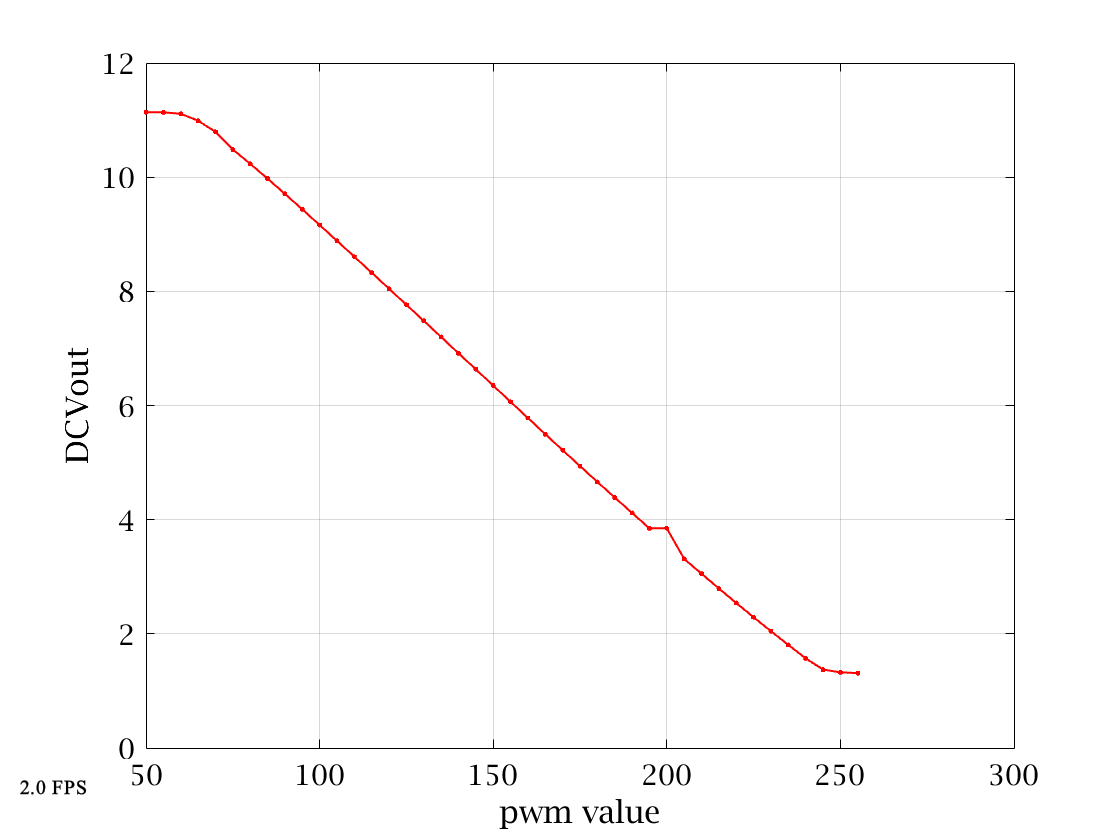

plot(pwm, v317, '.-'); xlabel('pwm value'); ylabel('DCVout'); grid;

Looks like the emitter follower pot could be tweaked a tad to make the slope a little flatter, but it won't make much difference -- we're still dropping a little at 250. The flat part below 50 is because the PWM voltage is too low to turn on T1 (so we think). 

## Modeling the circuit in Matlab 

Remember to always measure resistances with the power turned off. Measuring R2 is problematic after soldering in the circuit, because even with power off, the LM317 is still in parallel with it. Instead of turning it full clockwise, I turned it full counter-clockwise (lowest voltage) and measured R2 between ground and the unconnected terminal. Should be the same value, but without anything in parallel.

I copied the schematic below to keep it on the screen -- even better you should draw it (not print it), to have a working copy always in front of you for reference. The PWM ouput on D5 drives a 2 stage low-pass filter (R3+C3 and R4+C4). The first stage's impedance set by R3 won't unduely load D5 (5V/1k=5mA), and the larger 2nd stage's impedance, R4 won't onduly load the first stage. An emitter follower (T1) lowers R4's impedance by 1/hfe, driving current through R5 and R11 from Arduino's 5V supply, proportional to $( V_{T_1b} - V_{T_1be}-V_{T_2be})/(R_5+R_{11}) \approx (V_{PWM}-1.2) mA$. 

Copy of the schematic for easy reference. 

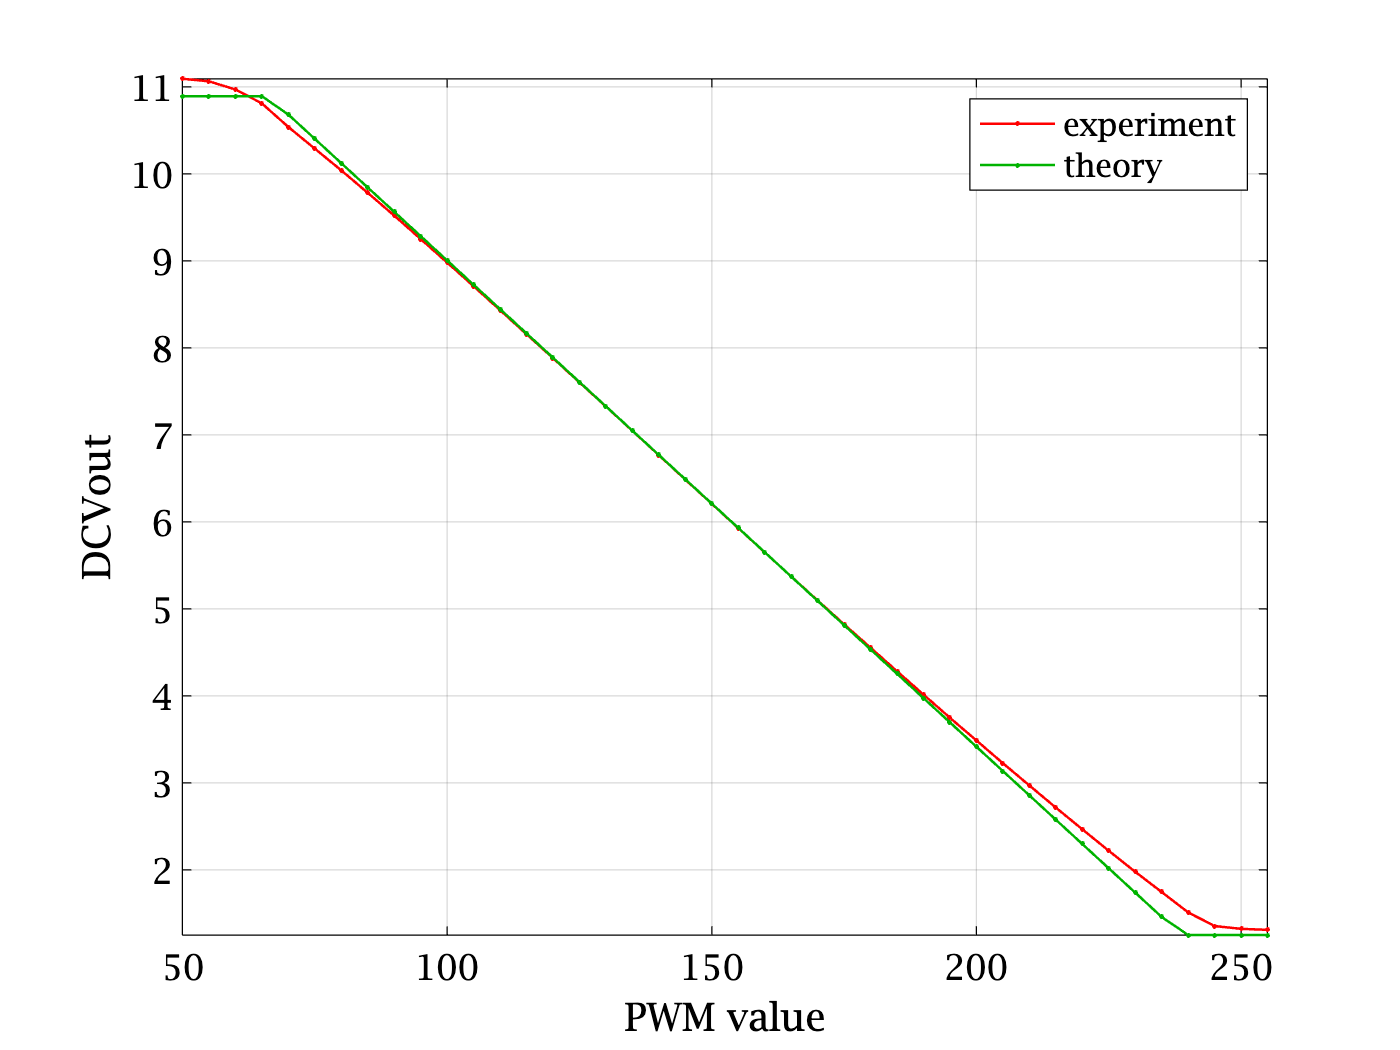

%% model 1
R1 = 1400; % ohms measured between LM317 pins 1 and 2 (with power off)
R2 = 10.8e3; % max ohms measured between ground and *unconnected* terminal
R5 = 3.5e3  ; % R5+R11, calling it R5
T1baseVoltage = pwm * vref / 255; % the PWM filter's gain = 1 at DC
T1emitterVoltage = T1baseVoltage -.6; % Vbe in saturation
T2collectorVoltage = 0.6; 
iMirror = (T1emitterVoltage-T2collectorVoltage) / R5; 
% if T1 isn't conducting then iMirror = 0:
iMirror(T1baseVoltage < 0.6 + T2collectorVoltage) = 0; 
iR1 = 1.25/ R1; % A, from LM317 datasheet. 50uA from iADJ
iR2 = iR1 - iMirror ; % KCL says iR1 = iR2 + iMirror
VR2 = iR2 * R2; 
DCVout = VR2 + 1.25; 
% the output is always less than input voltage - dropout voltage 
DCVout(DCVout < 1.25) = 1.25; % Vmin
plot(pwm, [v317 DCVout],'.-');
xlabel('PWM value'); ylabel('DCVout'); 
grid; axis tight;
legend('experiment','theory')

Reasonable (?) agreement with experiment. We were able to model  thresholds where the circuit behavior changes (e.g., saturation) using inline logic, i.e., `DCVout(DCVout > Vmax) = Vmax`; and `iMirror(T1baseVoltage < 0.6 + T2collectorVoltage) = 0; `instead of more verbose if/else constructs show the power of Matlab's syntax. Notice how this is different than how Eagle would simulate the circuit. We didn't model every component, e.g., the PWM filter doesn't appear ... because we're only modeling DC behavior and at DC the capacitors are infinite impedances (|1/j2*pi*infinity*C|). What about T1? It's emitter current < vref/R5 = 1.4mA,  divided by hfe~240 = 7uA base current through R3 and R4. That should cause a voltage drop at Vb by 7uA*(R3+R4) = 0.14V, a small effect, but we can model it that as a voltage divider with "R1" = R3+R4 = 22k, and "R2" = R5*hfe, so:

`T1baseVoltage = pwm * AREF / 255  * (R5*hfe)/(R5*hfe+22e3);`

We don't expect a huge effect, but let's see. 

### Model 2: with hfe

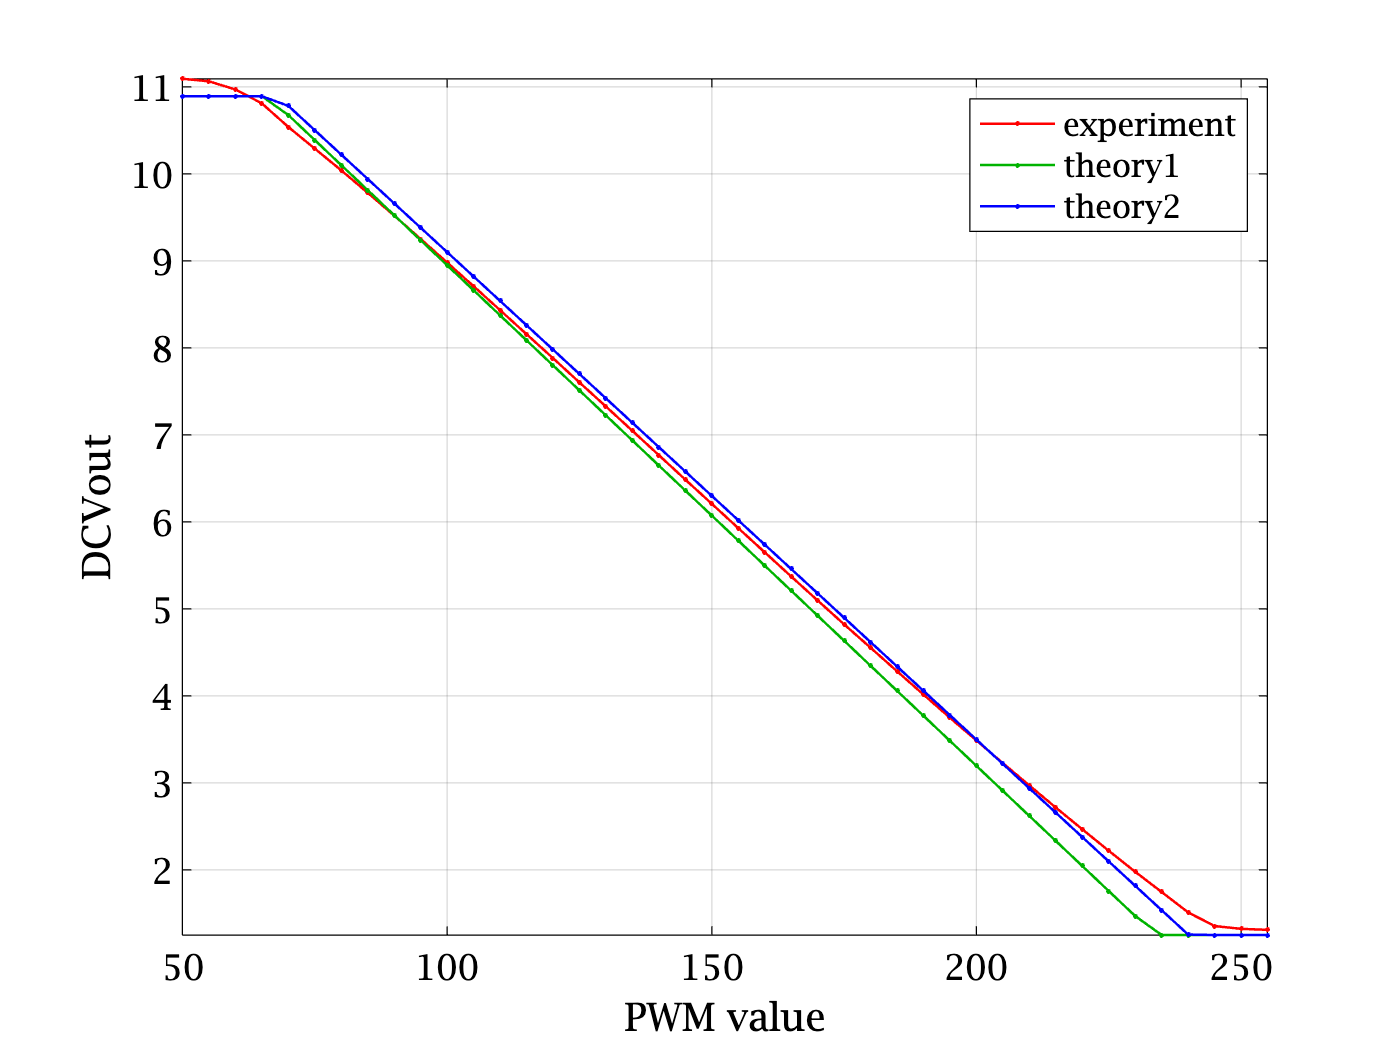

hfe = 240; % estimated
T1baseVoltage = pwm * vref / 255  * (R5*hfe)/(R5*hfe+22e3); % see below
T1emitterVoltage = T1baseVoltage -.6; % Vbe in saturation
iMirror = (T1emitterVoltage-T2collectorVoltage) / R5; % A
% if T1 isn't conducting then iMirror = 0:
iMirror(T1baseVoltage < 0.6 + T2collectorVoltage) = 0; 
iR1 = 1.25 / R1;
iR2 = iR1 - iMirror; % KCL says iR1 = iR2 + iMirror
VR2 = iR2 * R2; 
DCVout2 = VR2 + 1.25; 
DCVout2(DCVout2 > Vmax) = Vmax; 
DCVout2(DCVout2 < 1.25) = 1.25; % Vmin
plot(pwm, [v317 DCVout DCVout2]);
xlabel('PWM value'); ylabel('DCVout'); 
dots; grid; axis tight;
legend('experiment','theory1','theory2')

Not bad ... one more tweak: remember from the data sheet, Vout = 1.25*(1+R1/R2)+iAdj*R2, where iAdj ~ 25-50 microamps ... let's put some iAdj in the model: 

### Model 3, with IAdj 

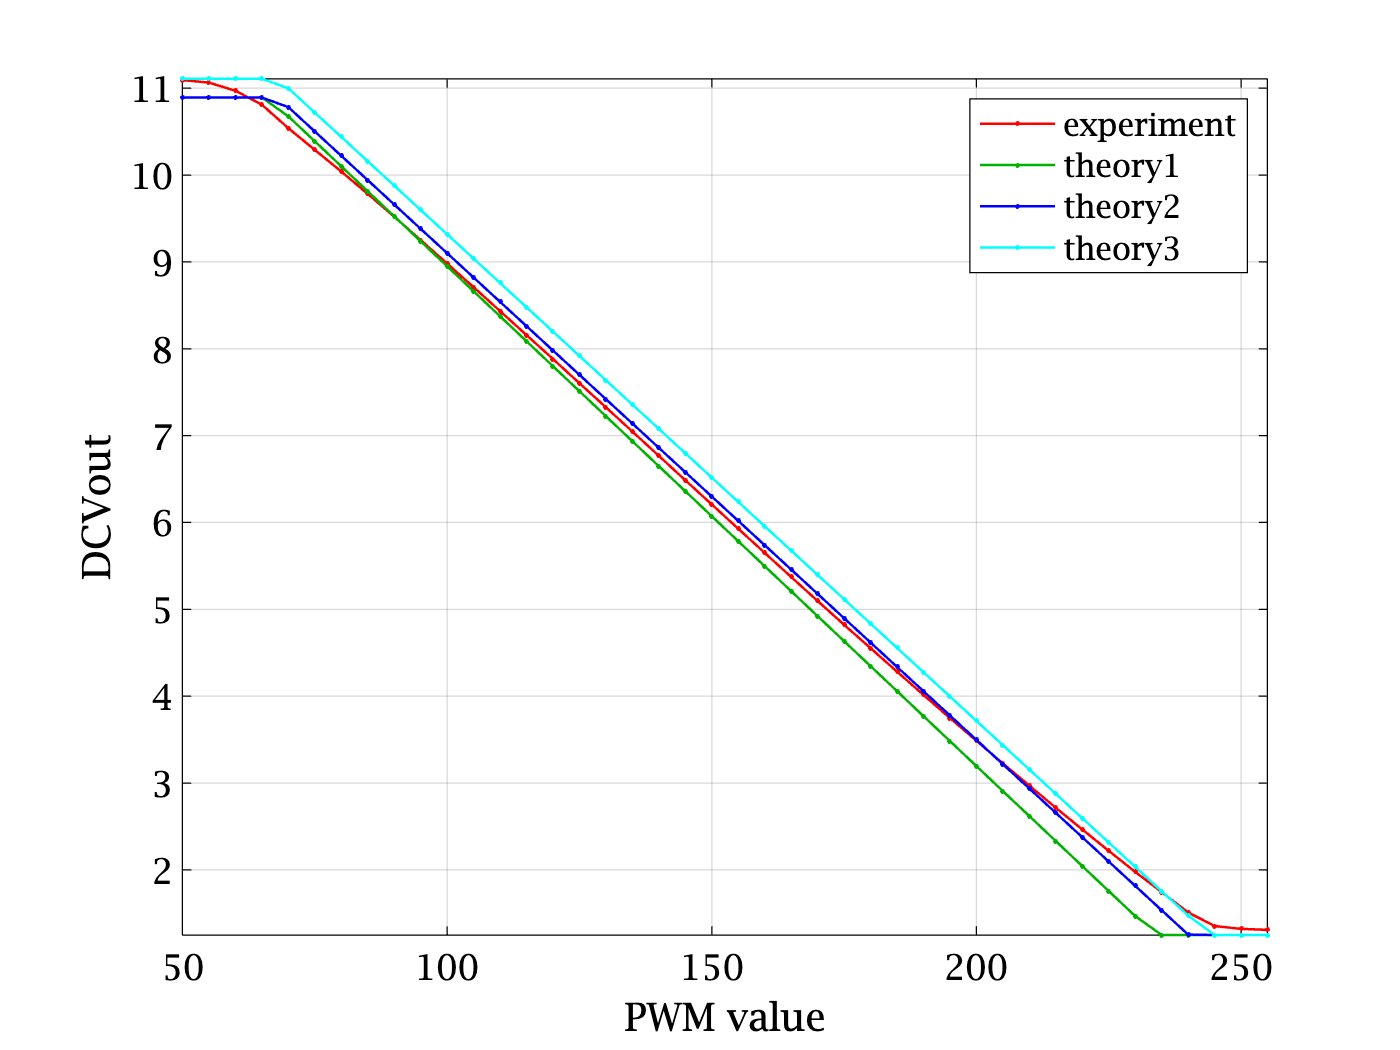


hfe = 240; % estimated
iAdj = 20e-6; % amps estimated
T1baseVoltage = pwm * vref / 255  * (R5*hfe)/(R5*hfe+22.2e3); % see below
T1emitterVoltage = T1baseVoltage -.6; % Vbe in saturation
iMirror = (T1emitterVoltage-T2collectorVoltage) / R5; % A
% if T1 isn't conducting then iMirror = 0:
iMirror(T1baseVoltage < 0.6 + T2collectorVoltage) = 0; 
iR1 = 1.25 / R1;
iR2 = iR1 + iAdj - iMirror; % KCL 
VR2 = iR2 * R2; 
DCVout3 = VR2 + 1.25; 
DCVout3(DCVout3 > Vmax) = Vmax; 
DCVout3(DCVout3 < 1.25) = 1.25; % Vmin
plot(pwm, [v317 DCVout DCVout2 DCVout3]);
xlabel('PWM value'); ylabel('DCVout'); 
dots; grid; axis tight;
legend('experiment','theory1','theory2','theory3')

## Discussion

We started by setting and measuring 42 different pwm and v317 voltage combinations. Even though each v317 datum was an average of 400 individual measurements, Arduino and Matlab measured these in merely 20 seconds. Our first model of the circuit focused on the main relationships between the DC voltages and currents, and certainly captured the key features of the experiment: the plateaus at top and bottom, and the approximate slopes and knees. Theory2 added explicit modeling of T1's base current, using a guesstimate of hfe that could easily be off by 20%, and it improved the fit with experiment. Theory3 added 20$\mu$A of IAdj (a guesstimate from the data sheet), which bracketed most experimental points between the first and last theory. 

It would be most dishonest to say these parameters and results just came out this way. I did a fair amount of trial and error ("drylab"). I looked at the initial errors and the equations to estimate which parameter changes will affect slope, intercept, and knee, and in which ways. Then the question becomes are the tweaks plausible? Are they within acceptable uncertainties, or do they suggest we're putting a big bandaid over a bad model? I think such trial-and-error tweaking is useful in telling us how robust the model (and the system) are to the parameters. 

The largest deviations between models and measurements are around the knees. The modeled transistors turn on and off precisely at $V_{BE} = 0.6V$, whereas real transistors have smoother transition regions, as indicated in the measurements. More complex model for the transistors would consider more accurately their transistions from off to conducting. But the key point is always, what do we want from a model, and when is it good enough to deliver that result? This one replicates the key characteristics of the PWM-Voltage relationship, qualitatively, and quantitatively, and gives us a good place to start trial-and-error parameter tweaking. The main goal here was to see if there was some fundamental behavior that we might have overlooked, and in this case, I don't see any. Not finding a problem doesn't mean there are none, but this independent assessment increases my confidence in this circuit. 

This PWM filter -> follower -> current mirror is a versatile module, and we'll find it can also be used to automate frequency control of our function generator, by simply soldering a parallel connection to the XR2206 frequency pot. The frequency pot programs a current throught the XR2206. A parallel current through our Arduino-controlled mirror will have the same result as reducing the resistance by turning the pot.

Hopefully this lab has improved your appreciation and understanding of automation and how it can be achieved with simple circuits. 

- From R's and C's we built filters to turn PWM signals into clean DC voltages. Transistors changed the impedances and converted analog voltages into currents, which controlled the LM317 integrated circuit voltage regulator. This was key for (at least) two reasons. One, the voltages on R1 and R2 of the LM317 would be fatal if they contacted an Arduino. The transistors provide isolation. Second, currents in parallel are "duals" to voltages in series. Providing a parallel current path to R2 meant we didn't have to give up manual control of R2.

- The mapping from PWM to voltage was modeled and measured rapidly/efficiently using automation. 

- Least-squares fit (Matlab's `polyfit`) gave us parameters to convert from one variable to another. 

- Serial communication between Matlab and Arduino is much faster than copy/pasting between the applications. 

- Formatting data in binary let us make an oscilloscope display with nearly real-time frame rates. 

- What else did you learn??

## A final (?) improvement ... 

Looking at the schematic it just occured to me that T1's collector doesn't need to jumper to the Arduino's 5V supply ... there's 12V on the bottom of the board that would work just as well. Think about how an emitter follower works: the emitter "follows" the base, $V_E = V_B-.6V$and the collector just has to be more than $V_B$, and capable of sourcing $h_{fe}*i_B$ of current. Connecting T1 to 12V saves a wire plugging into the Arduino, but T1 will have to dissapate a little more power. How much? Let's estimate that all the iMirror current comes from T1's collector (i.e., $h_{fe} = \infty$). Then T1 is sourcing: 

max(iMirror)

ans = 9.6989e-04

amps. Power = V*I, where $V=V_C-V_E = V_{CE}$. If we assume worst case, it's 12V (can't be any more), then T1 would be heating by ~1mA*12V ~ 12mW -- well within its ability to dissapate that heat. A better model would realize $V_E$ = max(iMirror)*(R5+R11), but we also already computed it:

PmaxT1 = max(iMirror) * (12 - max(T1emitterVoltage)) * 1000

PmaxT1 = 7.8584

multiplying by the unit conversion factor, (1000 mW/1W), for units of mW. Again, totally safe (and the extra work wasn't necessary). But this is a better circuit to solder (5V *was *more convenient for breadboarding because 12V isn't on top): one less jumper wire, and 1 less mA taken from the Arduino's (wimpy) voltage regulator and the USB. It is prudent to recheck calibration. I ran this file again, and the new experimental data (compared to the 3 theories) looks identical.  Revised schematic and board pictures are below, with the new 12V connection labeled in the photo.

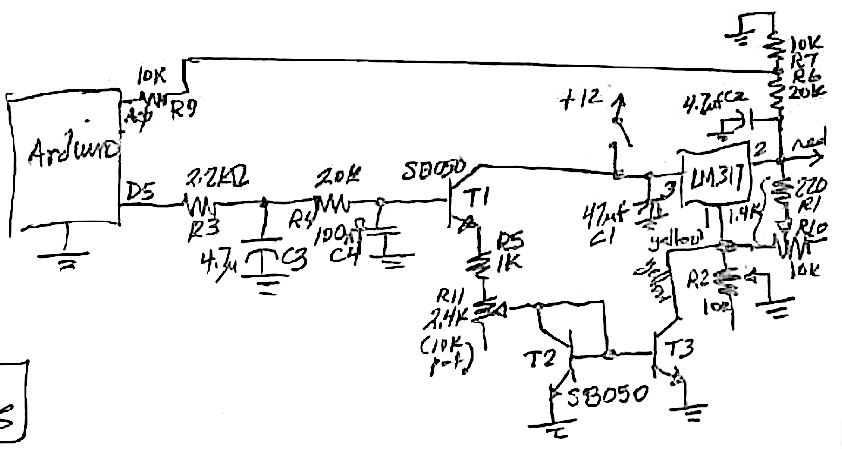

Final schematic, powering T1 from the 12V supply. 

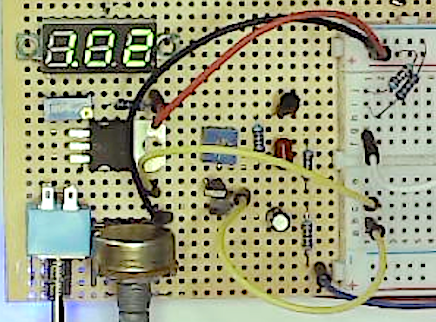 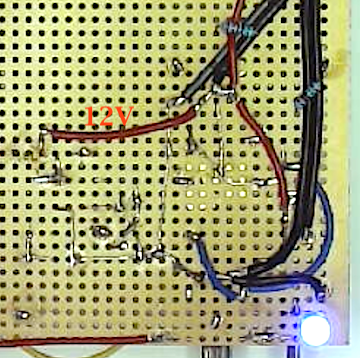

Blue jumper wire at bottom of left photo connects to D5 for PWM input, and yellow jumpers in middle are the current sink connected to R2 of the LM317 through lower column 1 of the solderless breadboard.